Initializing variables

clear all; close all; clc
load('out_MatRANS.mat');

% Creates the Uf field in MatRANS if it doesn't exists
% Spoiler alert: It does and this block does nothing
if ~isfield(MatRANS, 'Uf')
    MatRANS.Uf = sqrt(MatRANS.tau0/MatRANS.rho)
end

% Constants
nu = 1e-6; % Fluid kinematic viscosity (m^2/s)
beta = 9/100;

%import values from MatRANS
flow.y = MatRANS.y;
flow.h = flow.y(end);
% Take only last time step from time series data
flow.u_mean = MatRANS.u(end,:);
flow.k = MatRANS.k(end,:); %turbulent kinetic energy
% k(1) = 10e-4;
flow.omega = MatRANS.omega(end,:);
flow.Uf = MatRANS.Uf(end);

% Secondary Constants
flow.l = (beta^(-1/4)).*(sqrt(flow.k)./flow.omega);
%flow.v_prime_ms = 1./(3.*flow.k);
flow.v_prime_ms = flow.k ./ 3;
flow.Dt = flow.l ./ sqrt(flow.v_prime_ms);

% Non-dimensionalization
flow.U_mean = flow.u_mean ./ flow.Uf;
flow.DT = flow.Dt .* (flow.Uf/flow.h);
flow.Y = flow.y / flow.h;
flow.V_prime_ms = flow.v_prime_ms ./ flow.Uf;

flow.Y_bottom = 70*nu/flow.Uf/flow.h;



Calculation time!

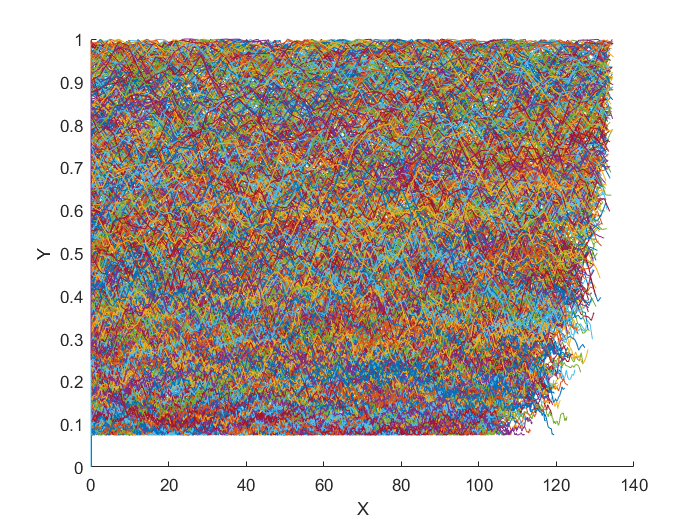

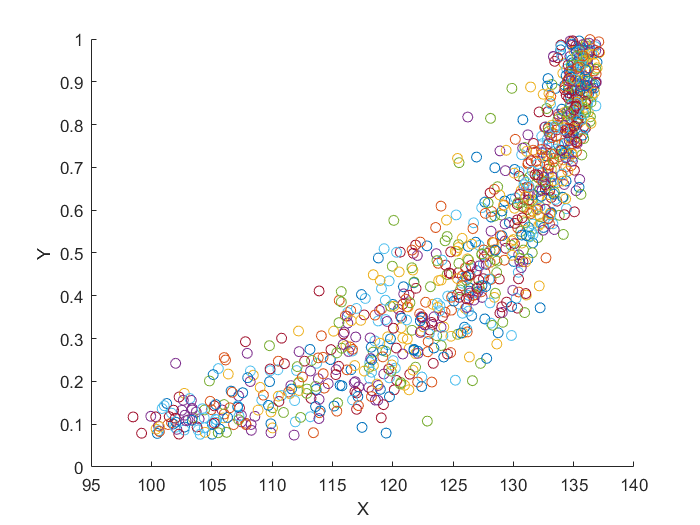

f1 = figure('Name', "Particle Trails");
xlabel('X');
ylabel('Y');
hold on

f2 = figure('Name', "Diffusion Cloud");
xlabel('X');
ylabel('Y');
hold on

N_particles = 1000;
for i_particle = 1:N_particles
    particle.X_line = zeros();
    particle.Y_line = zeros();
    
    % Initizalize particle parameters at T=0
    particle.T = 0;
    particle.X = 0;
    particle.Y = (flow.Y_bottom + (flow.Y(end) - flow.Y_bottom)*rand);
    particle.U_p = 0;
    
    while particle.T < 25
        particle.X_line = [particle.X_line, particle.X];
        particle.Y_line = [particle.Y_line, particle.Y];

        % Generate random value 
        a_r = randn;
        
        % Find flow parameters at particle Depth
        particle.DT = interp1(flow.Y, flow.DT, particle.Y);  
        particle.V_ms = interp1(flow.Y, flow.V_prime_ms, particle.Y);
        
        particle.DY = a_r .* sqrt(particle.V_ms) .* particle.DT;
        
        % Ensure particle stays within boundary
        particle.Y_next = particle.Y + particle.DY;
        if particle.Y_next > flow.Y(end)
            particle.Y_next = flow.Y(end) - (particle.Y_next - flow.Y(end));
        elseif particle.Y_next < flow.Y_bottom
            particle.Y_next = flow.Y_bottom - (particle.Y_next - flow.Y_bottom);
        end
        
        particle.U_p_next = (particle.U_p + interp1(flow.Y, flow.U_mean, particle.Y_next)) / 2;
        particle.DX = ((particle.U_p + particle.U_p_next)/2)*particle.DT;
        particle.X_next = particle.X + particle.DX;
        
        particle.T = particle.T + particle.DT;
        particle.X = particle.X_next;
        particle.Y = particle.Y_next;
    end
    figure(f1);
    plot(particle.X_line, particle.Y_line,'-');
    
    figure(f2);
    plot(particle.X, particle.Y,'o');
end